# Octahedral Shear Strain for Bimetallic Cable Under Tension

Solve a static structural model representing a bimetallic cable under tension, and compute octahedral shear strain.

Create a structural model.

structuralmodel = createpde('structural','static-solid');

Create the geometry and include it in the model. Plot the geometry.

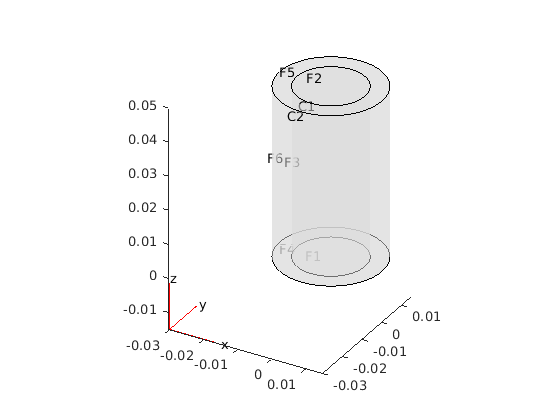

gm = multicylinder([0.01,0.015],0.05);
structuralmodel.Geometry = gm;
pdegplot(structuralmodel,'FaceLabels','on', ...
                         'CellLabels','on', ...
                         'FaceAlpha',0.5)

Specify the Young's modulus and Poisson's ratio for each metal.

structuralProperties(structuralmodel,'Cell',1,'YoungsModulus',110E9, ...
                                              'PoissonsRatio',0.28);
structuralProperties(structuralmodel,'Cell',2,'YoungsModulus',210E9, ...
                                              'PoissonsRatio',0.3);

Specify that faces 1 and 4 are fixed boundaries.

structuralBC(structuralmodel,'Face',[1,4],'Constraint','fixed');

Specify the surface traction for faces 2 and 5.

structuralBoundaryLoad(structuralmodel,'Face',[2,5], ...
                                       'SurfaceTraction',[0;0;100]);

Generate a mesh and solve the problem.

generateMesh(structuralmodel);
structuralresults = solve(structuralmodel)

structuralresults =   StaticStructuralResults with properties:

      Displacement: [1×1 struct]
            Strain: [1×1 struct]
            Stress: [1×1 struct]
    VonMisesStress: [22281×1 double]
              Mesh: [1×1 FEMesh]


Evaluate the principal strain at nodal locations.

pStrain = evaluatePrincipalStrain(structuralresults);

Use the principal strain to evaluate the first and second invariant of strain.

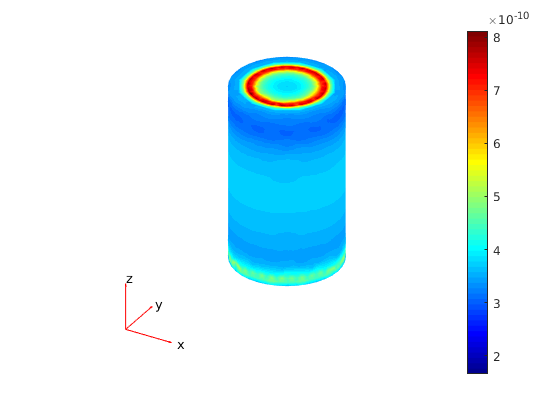

I1 = pStrain.e1 + pStrain.e2 + pStrain.e3;
I2 = pStrain.e1.*pStrain.e2 + pStrain.e2.*pStrain.e3 + pStrain.e3.*pStrain.e1;
tauOct = sqrt(2*(I1.^2 -3*I2))/3;
pdeplot3D(structuralmodel,'ColorMapData',tauOct)